# **drawCross**

Draw two intersecting lines perpendicular to each other.

## Description

## Syntax

drawCross(d1,d2,xc,yc)

drawCross(d1,d2,xc,yc,rot)

drawCross(d1,d2,xc,yc,rot,LineSpec)

p = drawCross(__)

### Description

drawCross(d1,d2,xc,yc)  draw cross with center (xc,yc) and length of arms  d1 and d2.

drawCross(d1,d2,xc,yc,rot)  draw cross at center (xc,yc) with length of arms  d1 and d2 and rotated by *rot* about the center.

p = drawCross(__) returns an output data.

### Method

The function **drawCross** call function **drawLine**.

The curve is plotted by MATLAB function [plot](https://www.mathworks.com/help/matlab/ref/plot.html).

## Arguments

### Input Arguments

**d1 **- length of cross arm in major direction

**d2 **- length of cross arm in minor direction

**xc       **-  center point

**yc       **- 

### **Optional Input Arguments**

**rot **- rotation angle in degrees, >0 is CCLW direction and <0 is CLW direction

### Optional Name-Value Pair Input Arguments

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with fields

- p.style - line style 

- p.width - line width 

- p.color - line color

## Examples

### Example 1

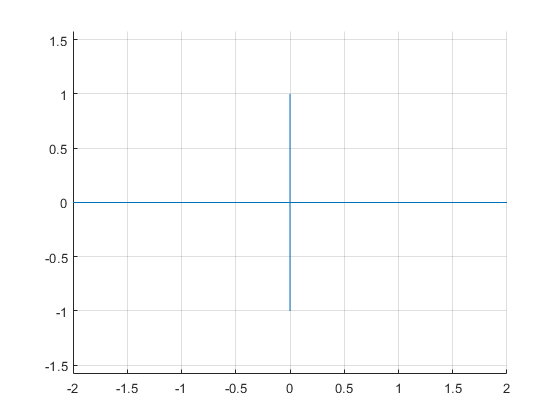

figure
hold on
axis equal
drawCross( 2, 1, 0, 0);
grid on

#### **Example 2**

figure
axis equal
hold on
p=drawCross(2,1,1,1,45,'r:')

p = struct with fields:
       xk: [-0.4142 2.4142 1.7071 0.2929 1]
       yk: [-0.4142 2.4142 0.2929 1.7071 1]
    color: [1 0 0]


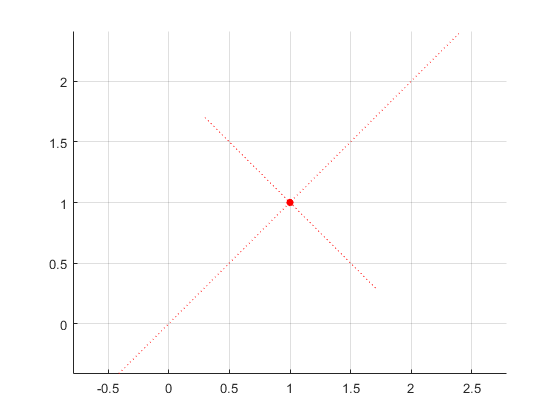

% plot referebnce points
scatter(1,1,30,'r','filled')
grid on

#### **Example 3**

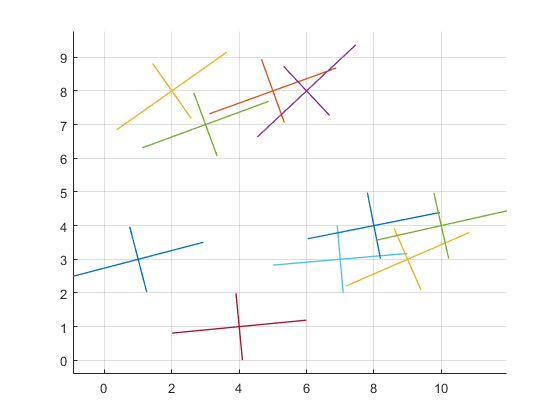

figure
axis equal
hold on
for k = 1:10
    drawCross(2,1,k,randi(10,1,1),45*rand,'LineWidth',1);
end
grid on

### Example 4

Principal components analysis in two-dimensions

drawInit
np = 1000;
xx = 10*randn(np,1);
yy = randn(np,1);
th = 180*rand(np,1);
x = xx.*cosd(th) - yy.*sind(th);
y = xx.*sind(th) + yy.*cosd(th);
scatter(x,y,20,'.')
p=PCA2d(x,y)

p = struct with fields:
     xm: -0.0716
     ym: 0.1032
     s1: 7.5353
     s2: 7.0537
    th1: -17.2350
    th2: 72.7650
      S: [2×2 double]
      C: [2×2 double]


p.C

ans =     0.9551   -0.2963
    0.2963    0.9551


[coeff]=pca([x,y])

coeff =     0.9551    0.2963
   -0.2963    0.9551


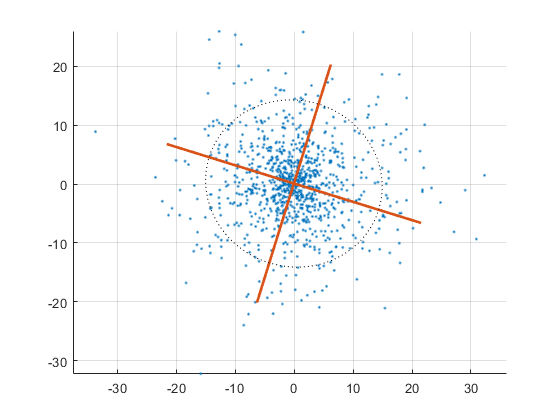

r1=drawCross(3*p.s1,3*p.s2,p.xm,p.ym,p.th1,'LineWidth',2);
drawEllipse(2*p.s1,2*p.s2,p.xm,p.ym,p.th1,'k:')
grid on

## See also

## References